clc; clear;
load('trainedSVM.mat', 'svmClassifierSaved');

% CNN on Characters Classification
charFolder = "Characters";
charValues = ["H", "D", "4", "4", "7", "8", "0", "A", "0", "0"];
charFiles = dir(fullfile(charFolder, "*.png"));

figure;
ImagesHD = zeros(128, 128, 1, length(charFiles));
features = zeros(length(charFiles), 128*128);

for k = 1:length(charFiles)
    charFilePath = fullfile(charFolder, charFiles(k).name);
    imageHD = imread(charFilePath);

    % Resize to [128, 128] and invert if necessary
    resizedImageHD = imresize(imageHD, [128, 128]);

    ImagesHD(:, :, 1, k) = resizedImageHD;
    features(k, :) = resizedImageHD(:)';
end

% Now resizedImagesHD has the correct dimensions for prediction with the SVM
predictedLabelHD = predict(svmClassifierSaved, features)

predictedLabelHD = 10×1 categorical array
     D 
     D 
     A 
     A 
     A 
     D 
     D 
     H 
     H 
     H 


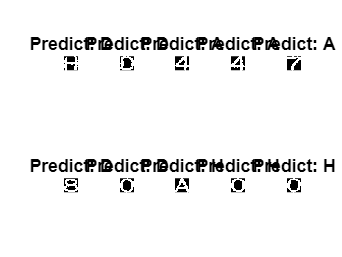

figure;
for k = 1:length(charFiles)
    subplot(2, 5, k); % Adjust the dimensions (2x5) as needed
    imshow(ImagesHD(:, :, 1, k));
    title(['Predict: ', char(predictedLabelHD(k))]);
end

## Improvement on data preprocessing - padding + dilating

% CNN on Characters Classification
charFolder = "Characters";
charValues = ["H", "D", "4", "4", "7", "8", "0", "A", "0", "0"];
charFiles = dir(fullfile(charFolder, "*.png"));

figure;
% Initialize resizedImagesHD with the correct dimensions: [128 128 1 Number_of_Images]
resizedImagesHD = zeros(128, 128, 1, length(charFiles));
paddedSize = [224 224];
features = zeros(length(charFiles), 128*128);

for k = 1:length(charFiles)
    charFilePath = fullfile(charFolder, charFiles(k).name);
    imageHD = imread(charFilePath);
    
    % If the image is RGB, convert it to grayscale
    if size(imageHD, 3) == 3
        imageHD = rgb2gray(imageHD);
    end

    % Resize to [128, 128] and invert if necessary
    resizedImageHD = imresize(~imageHD, [128, 128]);

    % Calculate padding
    paddingSize = paddedSize - size(resizedImageHD);
    padTop = floor(paddingSize(1)/2);
    padBottom = ceil(paddingSize(1)/2);
    padLeft = floor(paddingSize(2)/2);
    padRight = ceil(paddingSize(2)/2);

    % Padded to [156, 156]
    paddedImage = padarray(resizedImageHD, [padTop, padLeft], 1, 'pre');
    paddedImage = padarray(paddedImage, [padBottom, padRight], 1, 'post');

    % smooth edge
    se = strel('disk', 6); 
    erodedImage = imerode(paddedImage, se);
    
    % The padded image should be inserted into the 4th dimension of the array
    processedImage = imresize(erodedImage, [128 128]);
    resizedImagesHD(:, :, 1, k) = processedImage;
    features(k, :) = processedImage(:)';
end

% Now processedImage has the correct dimensions for prediction with the SVM
predictedLabelHD = predict(svmClassifierSaved, features)

predictedLabelHD = 10×1 categorical array
     H 
     0 
     4 
     4 
     7 
     H 
     0 
     A 
     0 
     0 


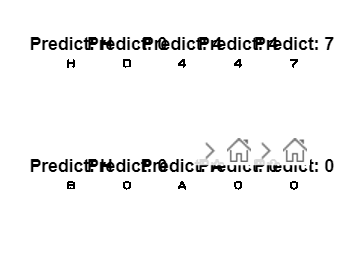

figure;
for k = 1:length(charFiles)
    subplot(2, 5, k); % Adjust the dimensions (2x5) as needed
    imshow(resizedImagesHD(:, :, 1, k));
    title(['Predict: ', char(predictedLabelHD(k))]);
end